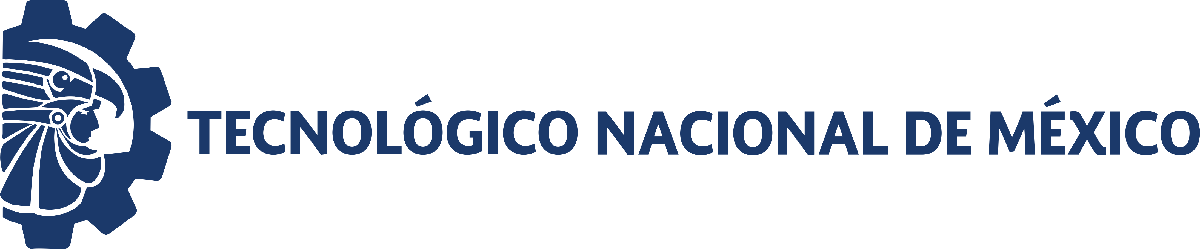                                 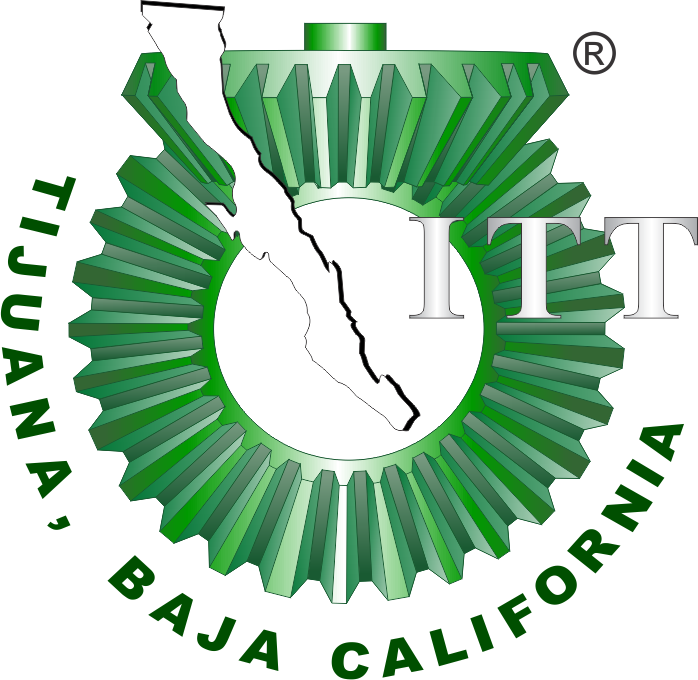

# Proyecto: Modelado y control del sistema pulmonar sano y con fibrosis

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

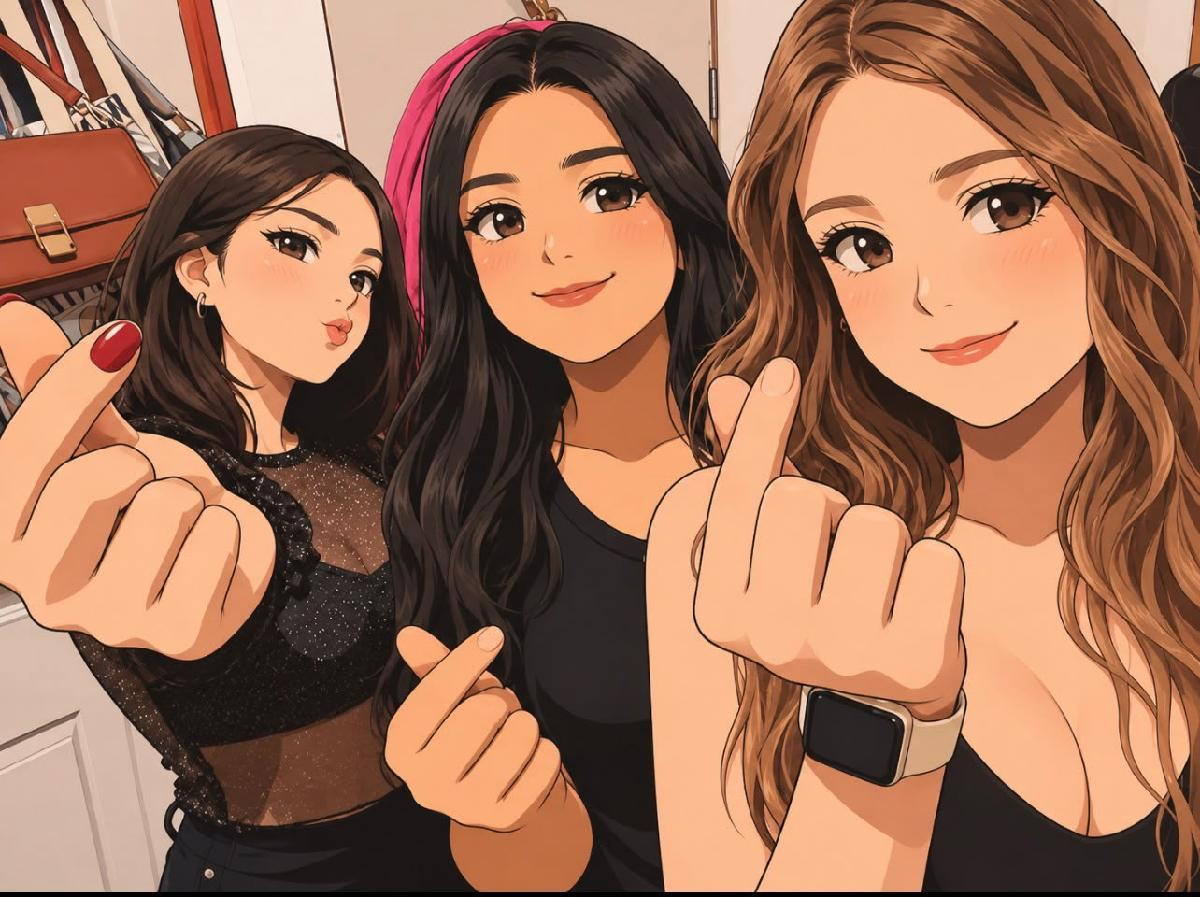

Nombre del alumno: **Ibarra Monroy Ivana Valeria, Muñoz Meneses Maria Luisa Michelle, Tirado Manzo Zulema Guadalupe **

Número de control: **23210709, 23210714, 23210724**

Correo institucional: **l23210724@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all;
warning('off','all')

modelo = 'Proyecto1';
open_system(modelo)

parameters.StopTime = '12';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
parameters.ReturnWorkspaceOutputs = 'on';

x = sim(modelo,parameters);

## **Respuesta a la señal sinusoidal**

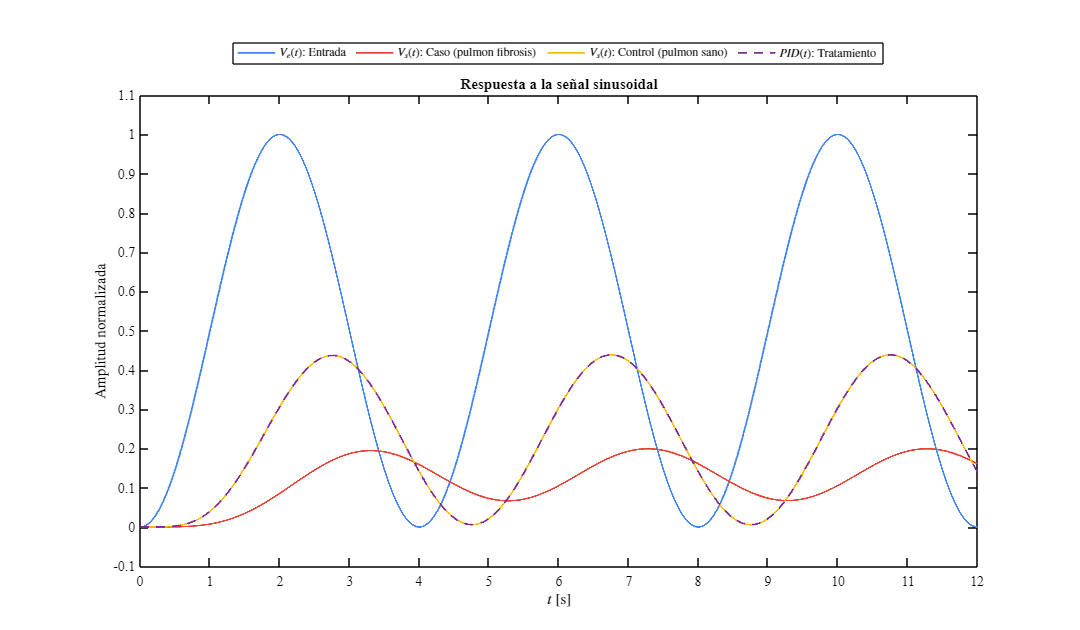

t = x.pulmones.time;
datos = x.pulmones.signals.values;

Ve = datos(:,1);
Vfibrosis = datos(:,2);
Vsano = datos(:,3);
PID = datos(:,end);

plotsignals(t,Ve,Vsano,Vfibrosis,PID,'Respuesta a la señal sinusoidal');

## Función: Respuestas de la simulación 

function plotsignals(t,Ve,Vsano,Vfibrosis,PID,signal)

set(figure(),'Color','w')
set(gcf,'Units','inches','Position',[0.5,0.5,12,7])
set(gca,'FontName','Times New Roman','FontSize',11)

hold on; grid off; box on;

clr1 = [66,133,244]/255;
clr2 = [234,67,53]/255;
clr3 = [251,188,5]/255;
clr4 = [126,47,142]/255;

order = [clr1;clr2;clr3;clr4];
colororder(order)

xlabel('$t$ [s]','Interpreter','latex')
ylabel('Amplitud normalizada','Interpreter','latex')

xlim([0 12]); xticks(0:1:12)
ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)

plot(t,Ve,'-', t,Vfibrosis,'-', t,Vsano,'-', t,PID,'--','LineWidth',1.5)

L = legend('$V_e(t)$: Entrada', '$V_s(t)$: Caso (pulmon fibrosis)','$V_s(t)$: Control (pulmon sano)','$PID(t)$: Tratamiento');

set(L,'Interpreter','latex','Location','northoutside','Orientation','horizontal')

title(signal,'Interpreter','none')

set(gcf,'Color','white')
set(gca,'Color','white','XColor','black','YColor','black')
set(L,'Color','white','TextColor','black')

exportgraphics(gcf,[signal '_Pulmones_matlab.pdf'],'ContentType','vector')
end

